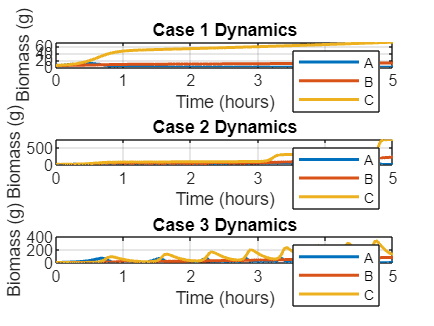

clear; clc; 

% Fixed parameters
alpha = 0.60;  
beta = 0.85;   
delta = 0.80;  
epsilon = 0.30;
eta = 0.60;

% Initial conditions [A, B, C, X]
y0 = [5; 5; 5; 0];
tspan = [0 5];

% Case parameters matrix [grA, grB, grC, drA, drB, drC]
cases = [0.2 0.2 0.2 0.1 0.1 0.1;    % Case 1
         0.65 0.7 0.1 0.02 0.02 0.01; % Case 2
         0.3 0.25 0 0.05 0.01 5];     % Case 3

%% Part B: Simulation
figure;
for case_num = 1:3
    % Extract parameters as vectors
    gr = cases(case_num,1:3);
    dr = cases(case_num,4:6);
    
    [t,y] = ode15s(@(t,y) system_eq(t,y,gr,dr,alpha,beta,delta,epsilon,eta), tspan, y0);
    
    subplot(3,1,case_num);
    plot(t, y(:,1:3), 'LineWidth', 1.5);
    title(sprintf('Case %d Dynamics', case_num));
    xlabel('Time (hours)');
    ylabel('Biomass (g)');
    legend('A', 'B', 'C');
    grid on;
end

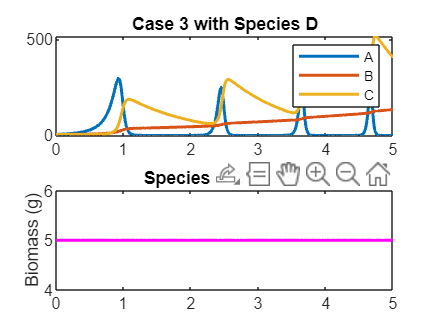

%% Part C: Introduce Species D
% New initial conditions with D
y0_D = [y0; 5];  % [A,B,C,X,D]
% Use Case 3 parameters
gr = cases(3,1:3);
dr = cases(3,4:6);

[t_D,y_D] = ode15s(@(t,y) system_with_D(t,y,gr,dr,alpha,beta,delta,epsilon,eta), tspan, y0_D);

% Plot results
figure;
subplot(2,1,1);
plot(t_D, y_D(:,1:3), 'LineWidth', 1.5);
title('Case 3 with Species D');
legend('A', 'B', 'C');

subplot(2,1,2);
plot(t_D, y_D(:,5), 'm', 'LineWidth', 1.5);
title('Species D Biomass');
ylabel('Biomass (g)');

Function file for system with species D

%% Part C: Introduce Species D

function dydt = system_with_D(t,y,gr,dr,alpha,beta,delta,epsilon,eta)
    % Original system
    dydt = system_eq(t,y(1:4),gr,dr,alpha,beta,delta,epsilon,eta);
    
    % Apply 80% inhibition to C's growth
    dydt(3) = dydt(3) * 0.2;
    
    % D's dynamics (constant population)
    dD = 0;
    
    dydt = [dydt; dD];
end

Function to provide the Differential Equations

function dydt = system_eq(t,y,gr,dr,alpha,beta,delta,epsilon,eta)
    A = y(1); B = y(2); C = y(3); X = y(4);
    
    dA = gr(1)*A - dr(1)*A + delta*A*B - epsilon*A*C;
    dB = gr(2)*B - dr(2)*B + eta*beta*B*X;
    dC = gr(3)*C - dr(3)*C + epsilon*A*C;
    dX = alpha*A - beta*B*X;
    
    dydt = [dA; dB; dC; dX];
end
